# Neural Networks

## What are neural networks?

**Neural networks** are a set of algorithms that are inspired by neural circuits in the brain. These algorithms can be computationally intensive, and have recently exploded in popularity due to advances in computing technology. 

Neural networks work by taking linear combinations of predictors to construct new representations of our features. Non-linear functions are applied to the new features to model the potential non-linearity in the dataset. This family of learning methods can be used for classification and regression problems.

### Modern applications of neural networks

Neural networks have been applied to several real-world problems, from[ determining medical diagnoses by classifying images](https://towardsdatascience.com/medical-diagnosis-with-a-convolutional-neural-network-ab0b6b455a20) to [training a self driving car](https://towardsdatascience.com/deep-learning-for-self-driving-cars-7f198ef4cfa2) to [biomedical text mining for extracting relevant patient information](https://medium.com/@Petuum/applying-neural-networks-to-biomedical-text-mining-fe655270c12). The main advantages of neural networks are the following:

- They can detect nonlinear relationships and interactions between predictor variables

- The mathematics underpinning neural networks relies less on statistical assuptions we usually impose in other models

- Neural networks are modular, and many architectures are available to model different problems

### Common components and notation of a neural network

There are [several flavors of neural network architectures](https://medium.com/cracking-the-data-science-interview/a-gentle-introduction-to-neural-networks-for-machine-learning-d5f3f8987786), each one having their own advantages and disadvantages for solving different problems. The diagram below illustrates a **feed-forward neural network**, where information flows forward from the input to the output, and no information feeds back into the network.

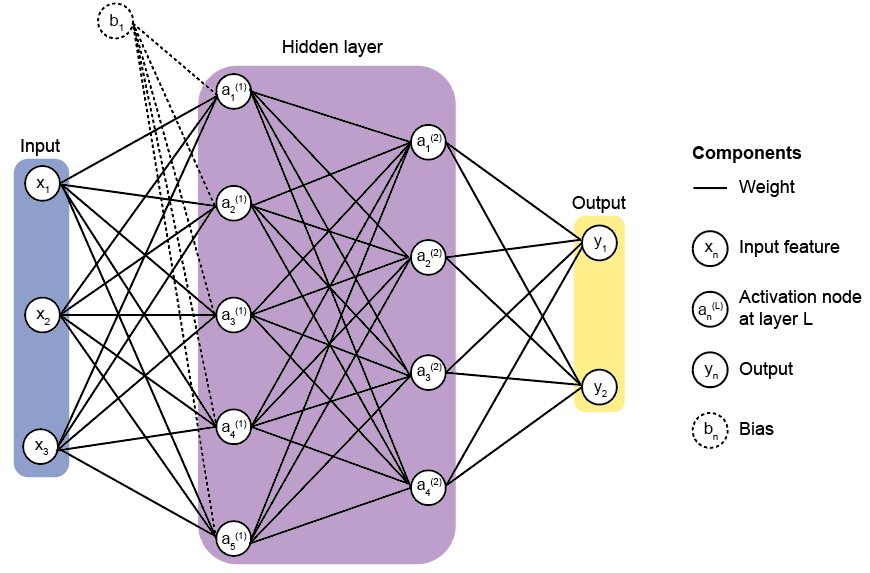

#### The input layer

Each node in the **input layer** represents a feature in the training data ($X_{\textrm{train}}$). Each edge corresponds to a **weight** vector. Further, we can choose to add more flexibility into the model by introducing some **bias** values. When we compute values in the activation node, we'll be solving equations that are analagous to the linear regression expression $Z\;=\;X\cdot \mathrm{weights}+\mathrm{bias}$.

#### The hidden layer(s)

The hidden layer is where the new values are stored from taking linear combinations of features from the input layer and applying non-linear transformations. These nodes are are known as **activation nodes**, and they represent a single new feature. 

A neural network with a single hidden layer is known as a **shallow neural network**. However, we can add more complexity in the model by adding more hidden layers and more activation nodes. Neural networks with more than 1 hidden layer are known as **deep neural networks** (DNNs), and the application of DNNs is known as **deep learning**. 

#### **The output layer**

From the last hidden layer, the values are transformed once more to the **output layer**. Here, we can use rules to turn these values into labels for a classification problem, or keep the raw values / probabilities in a regression problem. 

**To illustrate the main concepts underpinning neural networks for the next two lectures, we'll code up a shallow feedforward neural network from scratch.** There are three main phases in a feedforward neural network that we'll go over in depth:

- Constructing new features in **forward propagation**

- Evaluating the performance of forward prop using a **cost function**

- Tuning / correcting model parameters using **backward propagation**

## Step 1: Constructing new features using forward propagation

The training phase of a neural network is called [forward propagation](https://towardsdatascience.com/forward-propagation-in-neural-networks-simplified-math-and-code-version-bbcfef6f9250)**. **It consists of iteratively computing linear combinations of the input fed into each layer, followed by a non-linear transformation of the combined features. This is repeated for each hidden layer until we reach the output layer.

### Computing linear combinations of features 

Let's first use an artificial dataset to demonstrate what forward propagation does to our data. The example below uses a training dataset $X$ with 20 observations and 3 predictor variables.  

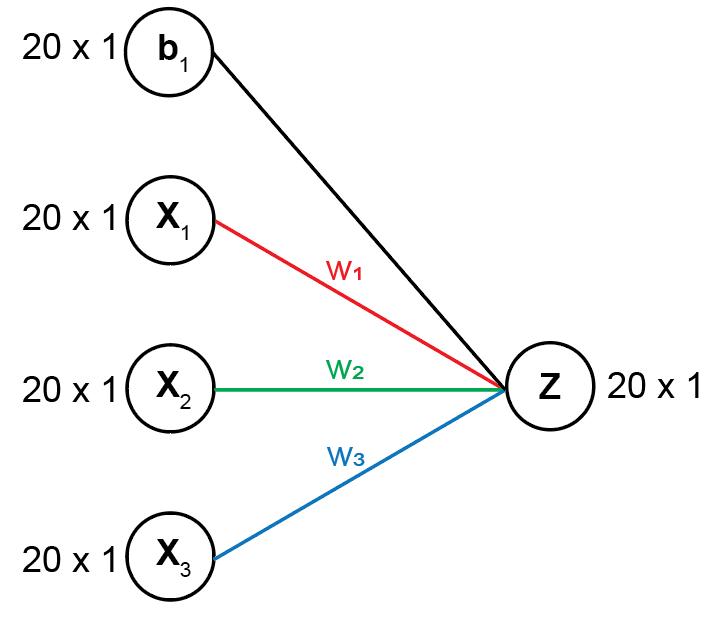

#### Analogy to linear regression

The formula to take a linear combination of predictors is shown below. The new features are stored in the variable `Z`.


$$Z=Xw^T +b$$


While this problem is slightly different from a linear regression problem in that we are solving for the output `Z` rather than using `X` and `Z` to estimate our coefficients, we actually have the same objective, and we're trying to estimate two parameters: 

- The **weights** ($w$), which is equivalent to the regression coefficients $\beta$

- The **bias** ($b$) values, which is equivalent to the intercept $\beta_0$. 

#### Impact of weights on the new feature `Z` generated by the neural network 

For now, let's see how the two parameters $w$ and $b$ affect the solution $Z$, and then plot the relationship between $X$ and $Z$. We'll take the linear combinations with 1 to 3 weights and biases of different values. 

% Initialize inputs using random numbers using a fixed random number generator (rng)
% for reproducibility
rng(2);
X = normrnd(0, 1, [20, 3])

X =    -0.1242    0.0125    1.4454
   -2.5415   -1.0163    0.0000
    0.2772   -0.1156    2.8467
   -0.1960   -0.7763   -0.3859
   -0.1962   -1.1398    0.1502
   -0.3057    0.3198   -0.3172
   -1.1289   -0.5715   -0.1628
    0.1942   -1.6300    0.8194
   -0.6071   -0.9364    0.0817
   -0.8284   -0.2786    1.9564


b = randn([20, 1])

b =     1.1527
    0.3926
    0.7993
   -1.9146
   -0.5855
    0.0593
   -0.5918
   -2.4356
    1.8796
   -0.1841


#### Solution using 1 weight value

The following network diagram using 1 weight value is shown below:

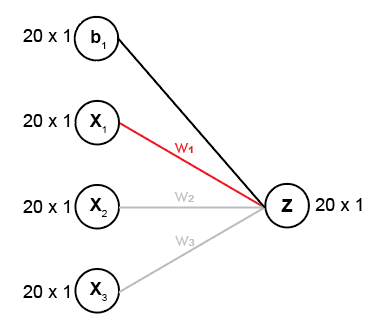

Which is equivalent to solving the following set of equations:


$$Z=X_1 w_1 +b$$


As you can see, the new feature $Z$ will most resemble $X_1$, shown in the scatter plot below.

% Weight vectors
w = [1, 0, 0]; % Only 1 weight
Z1 = X * w' + b

Z1 =     1.0285
   -2.1489
    1.0765
   -2.1106
   -0.7817
   -0.2464
   -1.7207
   -2.2414
    1.2725
   -1.0125


Let's now plot the relationship between each feature in $X$ and the output $Z$. 

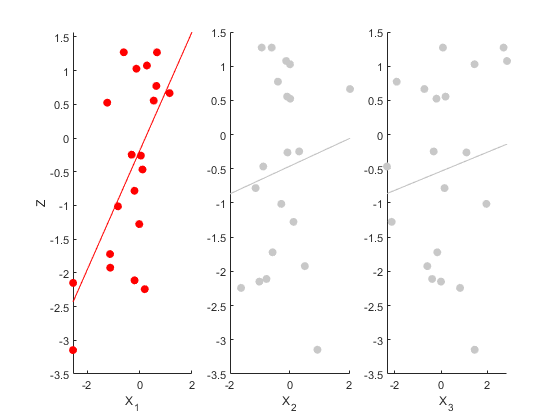

figure; gray = [200,200,200]/255; 
subplot(1, 3, 1); scatter(X(:, 1), Z1, 'red', 'filled')
xlabel('X_{1}');  ylabel('Z'); set(lsline, 'color', 'r')
subplot(1, 3, 2); scatter(X(:, 2), Z1, [], gray, 'filled')
xlabel('X_{2}');  lsline
subplot(1, 3, 3); scatter(X(:, 3), Z1, [], gray, 'filled')
xlabel('X_{3}');  lsline

Note that the slight positive relationship between $X_2$ or $X_3$ and $Z$ is not meaningful, but is an artificact of the small number of observations we used to make $X$ and random chance.

#### Solution using 2 weight values

If we include two weights, the network will look like the following diagram:

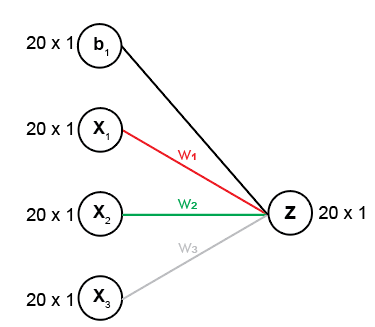

And the system of equations will look like the following:


$$Z=X_1 w_1 +X_2 w_2 +b$$


You will notice that there is a stronger correlation between the new feature $Z$ and $X_2$, as it is assigned a higher weight.

% Compute Z = x1w1 + x2w2 + x3w3 + b
w = [1, 2, 0]; % 2 weights only
Z2 = X * w' + b

Z2 =     1.0535
   -4.1814
    0.8453
   -3.6632
   -3.0614
    0.3931
   -2.8636
   -5.5014
   -0.6003
   -1.5698


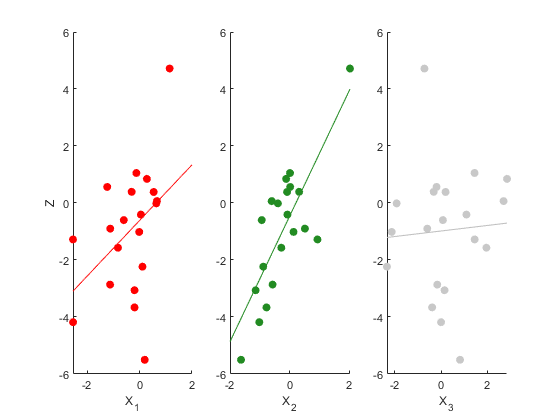

% Make plot
figure; green = [34, 139, 34] ./ 255;
subplot(1, 3, 1); scatter(X(:, 1), Z2, 'red', 'filled')
xlabel('X_{1}');  ylabel('Z'); set(lsline, 'color', 'r')
subplot(1, 3, 2); scatter(X(:, 2), Z2, [], green, 'filled')
xlabel('X_{2}');  set(lsline, 'color', green)
subplot(1, 3, 3); scatter(X(:, 3), Z2, [], gray, 'filled')
xlabel('X_{3}');  lsline

#### Solution using 3 weight values

Finally, let's include a fully connected hidden layer with all 3 weights.

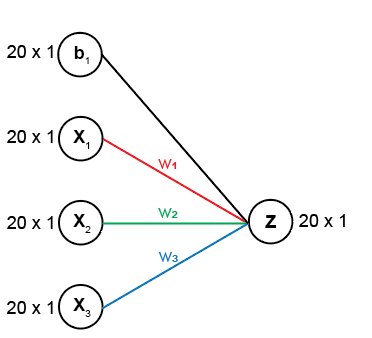

Where the complete set of linear equations to solve will be:


$$Z=X_1 w_1 +X_2 w_2 +X_3 w_3 +b$$


% Compute Z = x1w1 + x2w2 + x3w3 + b
w = [1; 2; -5]; % All 3 weights
Z3 = X * w + b

Z3 =    -6.1737
   -4.1815
  -13.3883
   -1.7339
   -3.8122
    1.9791
   -2.0497
   -9.5984
   -1.0088
  -11.3516


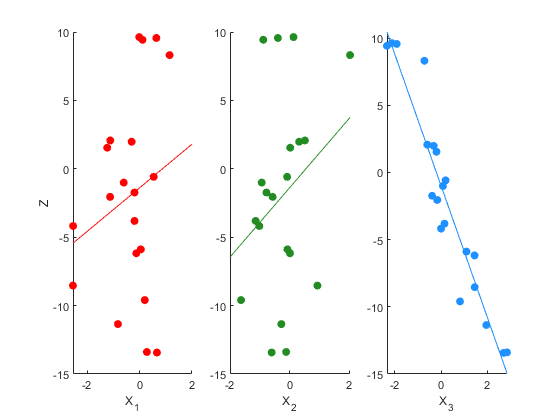

% Make plot
figure; blue = [30, 144, 255] ./ 255;
subplot(1, 3, 1); scatter(X(:, 1), Z3, 'red', 'filled')
xlabel('X_{1}');  ylabel('Z'); set(lsline, 'color', 'r')
subplot(1, 3, 2); scatter(X(:, 2), Z3, [], green, 'filled')
xlabel('X_{2}');  set(lsline, 'color', green)
subplot(1, 3, 3); scatter(X(:, 3), Z3, [], blue, 'filled')
xlabel('X_{3}');  set(lsline, 'color', blue)

We have a new complex feature that is positively correlated with $X_1$ and $X_2$, but negatively correlated with $X_3$,

#### Takeaways

As you can see with the boxplot above, different combinations of weights dramatically the distribution of the final computed predictor `Z`, and creates more complex features`.` Thus, the weights are a really important parameter to tune in the model.

#### How do we initialize the weights and biases in practice?

Without knowing the true relationship between the predictor and response variables, we need to initialize the weight and bias parameters somehow. It turns out that[ intializing neural networks with small and random values for w and b is a better way](https://machinelearningmastery.com/why-initialize-a-neural-network-with-random-weights/) to train these parameters than setting them to all zero or one. We'll explore this idea further later in the lecture.

### Non-linear transformations using an activation function

In this section, we'll discuss different ways to add non-linearity into the computed variable `Z`, and the advantages / disadvantages of each method.

#### The sigmoid activation function

One way to transform the data is to use the sigmoid activation function (aka logit transformation) to transform our data into probabilities with values ranging from [0, 1]. The formulation of the sigmoid activation function is:


$$\textrm{sigmoid}\left(Z\right)=A=\frac{1}{1+e^{-Z} }$$


And the shape of the sigmoid distribution is shown below:

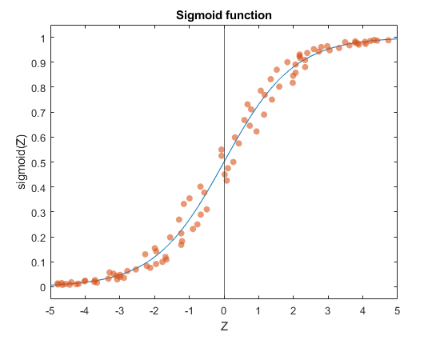

To access all the activation functions described in this lecture, we can use the `activationFnc` script provided in the project folder (documentation described below) to transform our values.

**Applying the sigmoid activation function to **`Z`

Let's see what happens when we apply the sigmoid activation function element-wise to the three Z vectors we computed in the previous section from introducing different weights.

% Compute y using the Z1 cell array containing the results from using different w values
Z = [Z1, Z2, Z3]                % Store all Z values in single array to perform 1 computation

Z =     1.0285    1.0535   -6.1737
   -2.1489   -4.1814   -4.1815
    1.0765    0.8453  -13.3883
   -2.1106   -3.6632   -1.7339
   -0.7817   -3.0614   -3.8122
   -0.2464    0.3931    1.9791
   -1.7207   -2.8636   -2.0497
   -2.2414   -5.5014   -9.5984
    1.2725   -0.6003   -1.0088
   -1.0125   -1.5698  -11.3516


A = activationFnc(Z, 'Sigmoid') % Scaled from 0 -> 1 using sigmoid activation function

A =     0.7366    0.7414    0.0021
    0.1044    0.0150    0.0150
    0.7458    0.6996    0.0000
    0.1081    0.0250    0.1501
    0.3139    0.0447    0.0216
    0.4387    0.5970    0.8786
    0.1518    0.0540    0.1141
    0.0961    0.0041    0.0001
    0.7812    0.3543    0.2672
    0.2665    0.1722    0.0000


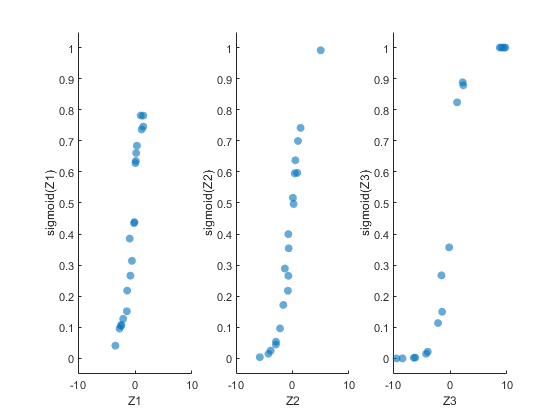

% Plot 3 sigmoid curves
figure;
for i = 1:size(Z, 2)
    subplot(1, 3, i)
    scatter(Z(:, i), A(:, i), ...
            'filled', 'o', 'MarkerFaceAlpha', 0.6, ... 
            'jitter', 'on', 'jitterAmount', 0.5);       
    xlabel(strcat('Z', string(i))); ylabel(strcat('sigmoid(Z', string(i), ')'));
    ylim([-0.05, 1.05]); xlim([-10, 10]);
end

Applying the sigmoid activation function transforms our each $Z$ vector scales the data from $\left\lbrack 0,1\right\rbrack$ and also generates the characteristic sigmoid curve. This feature of the sigmoid activation function is especially useful for binary classification.

### Rectified linear units (ReLUs) 

While the `Sigmoid` activation function is easy to interpret and is simple to apply, there are issues with using it as an activation function:

- With each iteration, the $e^{-Z}$ term in the `sigmoid` function becomes infinitesimally small. When correcting our parameters in back propagation (covered in the next section), correcting these extremely small values result in slower updates. This is called the **vanishing gradient problem**, and is an issue when it comes to optimizing neural network parameters using gradient descent.

- Further, our values are between 0 and 1. This is not really useful for regression problems.

Thus, people have been turning to the ReLU as the preferred activation function, especially for more complex neural network architectures. The formulation of the **ReLU** is shown below, and is really simple:


$$\textrm{ReLU}\left(z\right)=\left\lbrace \begin{array}{cc}
z & \textrm{if}\;z>0\\
0 & \textrm{if}\;z\le 0
\end{array}\right.$$


This basically sets negative values to 0, while leaving the original transformed value intact. The ReLU activation function has the following non-linear distribution shape:

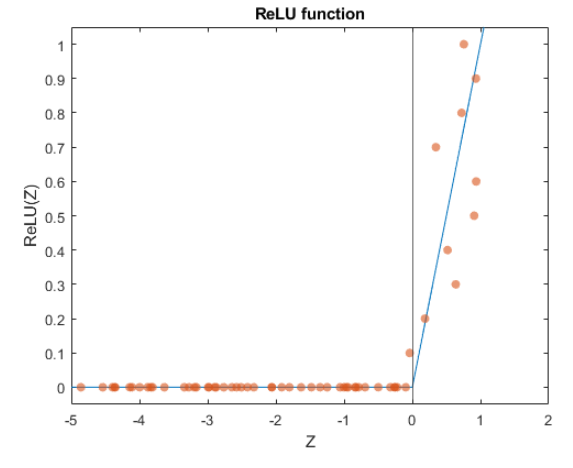

The ReLU has gained popularity in recent years because it takes care of the problems faced by the Sigmoid activation function, such as:

- The correction term in back propagation is not infinitesimally small. This rectifies the vanishing gradient problem.

- Because only a few neurons would be activated (negative values are all 0), this makes the model more efficient.

### Leaky rectified linear units (Leaky ReLUs) 

The ReLU does have its own set of problems, such as handling real negative values (since they're set to 0, the model will essentially ignore these values). 

There is an improved method of the ReLU: the** leaky ReLU**! Instead of setting to value to 0 for negative numbers, we'll scale the negative values using a small weight (usually this weight, which we'll denote as epsilon ($\varepsilon$) is set to 0.01). This will cause a smaller gradient to flow for the negative values, and thus improves our performance with negative numbers.

The formulation for the leaky ReLU is


$$\textrm{Leaky}\;\textrm{ReLU}\left(Z\right)=\left\lbrace \begin{array}{cc}
z & \textrm{if}\;z\;\textrm{is}\;\textrm{positive}\\
\varepsilon \cdot z & \textrm{if}\;z\;\textrm{is}\;\textrm{negative}
\end{array}\right.$$


The leaky ReLU has the following distribution shape:

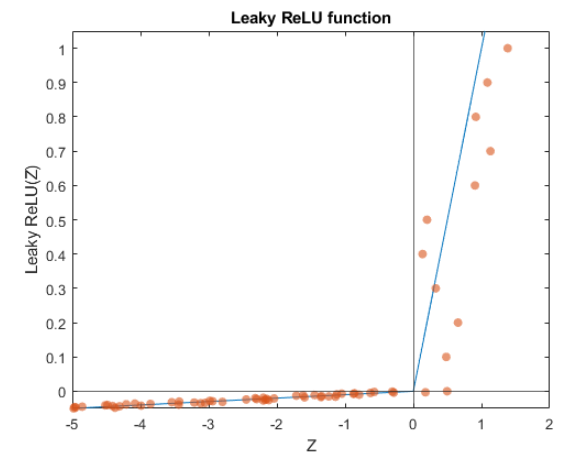

Now that we have covered a single round of combing features and adding non-linearity to the combined features, we have the tools to run a full round of forward propagation. 

### A single round of forward propagation

Let's now put all of these concepts together to run 1 round of forward propagation with **no hidden layer** using a breast cancer dataset built into MATLAB. Without the hidden layer, we're performing a model that is essentially the combination of linear and logistic regression! 

#### Description of breast cancer dataset

The dataset can be called using the `load cancer_dataset `command, and a comprehensive description of the dataset can be found by typing in `help cancer_dataset`. Some relevant notes about the dataset:

- The input is a matrix of 9 features from 699 biopsies. The features include attributes such as adhesion, cell size, and cell shape. These are stored in the `cancerInputs` variable. 

- The `cancerTargets` variable is a 2 x 699 matrix, where the first column corresponds to benign, and the the second column corresponds to malignant. Thus, we will perform binary classification.

clear all;
load cancer_dataset.mat

% View input dataset. Rows = features. Columns = observations
data = array2table(cancerInputs, ...
    "RowNames", {'Clump thickness', 'Uniform Cell size', ...
    'Uniform Cell shape', 'Adhesion', 'Single cell size', ...
    'Bare nuclei', 'Bland chromatin', 'Normal nucleoli', ...
    'Mitoses'})

data = 9×699 table
                          cancerInputs1    cancerInputs2    cancerInputs3    cancerInputs4    cancerInputs5    cancerInputs6    cancerInputs7    cancerInputs8    cancerInputs9    cancerInputs10    cancerInputs11    cancerInputs12    cancerInputs13    cancerInputs14    cancerInputs15    cancerInputs16    cancerInputs17    cancerInputs18    cancerInputs19    cancerInputs20    cancerInputs21    cancerInputs22    cancerInputs23    cancerInputs24    cancerInputs25    cancerInputs26    cancerInputs27    cancerInput

% View target dataset. Rows = targets. Columns = observations
target = array2table(cancerTargets, ...
    "RowNames", {'Benign', 'Malignant'})

target = 2×699 table
                 cancerTargets1    cancerTargets2    cancerTargets3    cancerTargets4    cancerTargets5    cancerTargets6    cancerTargets7    cancerTargets8    cancerTargets9    cancerTargets10    cancerTargets11    cancerTargets12    cancerTargets13    cancerTargets14    cancerTargets15    cancerTargets16    cancerTargets17    cancerTargets18    cancerTargets19    cancerTargets20    cancerTargets21    cancerTargets22    cancerTargets23    cancerTargets24    cancerTargets25    cancerTargets26    cancerTargets27   

The model schematic and an overview of the computations we will be performing is shown below. 

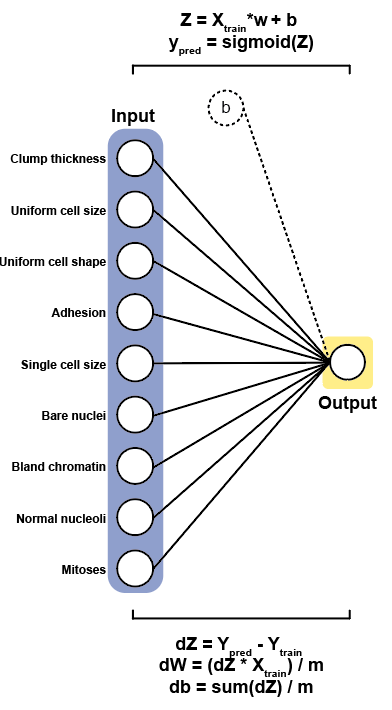

Let's now create the variables we'll need to train and test the model:

% Set seed for reproducibility
rng(2);

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(cancerInputs', cancerTargets(1, :)', ...
    trainingSize, randomstate);

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);
Xtrain = (Xtrain - mu) ./ sigma; Xtest = (Xtest - mu) ./ sigma;

#### Intialize variables needed to run forward propagation

Our objective is to compute 1 output vector for the binary classification problem. Further, we're going to use the sigmoid activation function, which is essentially equivalent to performing logistic regression.

% Intialize the hyperparameters 
numberOutputNodes = 1; actFnc = 'Sigmoid';

% Intialize the weights and biases. w size should be number of features x number of activation nodes
w = randn([size(Xtrain, 2), numberOutputNodes])

w =    -0.1741
   -1.4407
   -0.0709
   -1.3681
   -1.4625
   -0.0212
    1.2875
   -2.7914
   -1.3112


% b size should be number of observations in training data x 1
b = randn([size(Xtrain, 1), 1])

b =     1.4754
    0.4140
    0.4951
    2.1199
   -0.4965
    0.4568
   -0.3635
    0.9546
    0.4000
   -0.5168


#### Forward propagation

Let's now run forward propagation from the input layer to the output layer:

Z = Xtrain * w + b

Z =     5.6920
    5.1753
    4.5263
   -5.2689
    2.5367
    2.5105
  -16.0270
    5.5922
    4.9759
   -8.7984


ypred = activationFnc(Z, actFnc)

ypred =     0.9966
    0.9944
    0.9893
    0.0051
    0.9267
    0.9249
    0.0000
    0.9963
    0.9931
    0.0002


Now we need to now see how well our model performed using a cost function.

## Step 2: Evaluating the model fit using the cost function

Next, we need to evaluate how well our model has performed in it's initial pass through using a cost function. Because we are performing a binary classification problem, we can use the **cross-entropy cost function.**

### **Cross-entropy cost function**

Recall the formulation for the Cross-Entropy cost function:


$$J=-\frac{1}{m}\sum_{i=1}^m \left\lbrack -{y_{\mathrm{train}} }^{\left(i\right)} \mathrm{log}\left(y_{\mathrm{pred}}^{\left(i\right)} \right)-\left(1-{y_{\mathrm{train}} }^{\left(i\right)} \right)\mathrm{log}\left(1-y_{\mathrm{pred}}^{\left(i\right)} \right)\right\rbrack$$


where $m$ are number of observations, $y_{\textrm{train}}$ is the response variable, and $y_{\textrm{pred}}$ is a vector of the predicted value from forward propagation. 

The **cost** value (`J)` can be computed using the `costFunction` function provided. The docstring is provided below:

% There will be two loss values: one for the malignant target and the other
% for the benign target
lossFunction = 'Log-Loss';
J = costFunction(Ytrain, ypred, lossFunction)

J = 0.2742

Now that we have a cost value, we can start to optimize our neural network algorithm using backward propagation.

## Step 3: Optimizing `w` and `b` parameters using backward propagation

After computing the cost, we know how good or how bad our model performed overall. In neural networks, we need to tell the algorithm how to adjust the weight and bias parameters so that the cost goes down in the next iteration,  until we reach a stable minimum cost value. This process is called **back propagation**, and the optimization algorithm we use to update the weights and the biases is **gradient descent**. 

### Finding the gradients dW and db using back propagation

The objective of back propagation is to determine how much we should change `w` and `b` such that we minimize the cost. Thus, we need to find an expression that allows us to relate the cost back to the parameter`. `The **gradient**, or the values from solving partial differential equations of the cost with respect to W ($\frac{\vartheta J}{\vartheta W}$) and b ($\frac{\vartheta J}{\vartheta b}$) will tell us how much error a specific activation node contributes to the overall model error.

#### Intuition for back propagation 

Formulated below are the expressions needed to solve $\frac{\vartheta J}{\vartheta W}$ and  $\frac{\vartheta J}{\vartheta b}$ for each layer:

$\frac{\vartheta J}{\vartheta W}$ = $\frac{\vartheta J}{\vartheta y}\cdot \frac{\vartheta y}{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta W}$ 

$\frac{\vartheta J}{\vartheta b}$ = $\frac{\vartheta J}{\vartheta y}\cdot \frac{\vartheta y}{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta b}$ 

Let's consider the gradient $\frac{\vartheta J}{\vartheta W}$ (the same logic applies for $\frac{\vartheta J}{\vartheta b}$) and work backwards from the output layer to the input layer. There are three places where the model can go wrong: 

- From the output layer to the hidden layer ($\frac{\vartheta J}{\vartheta y}$). A natural expression to compute this error is $Y_{\textrm{pred}} -Y_{\textrm{train}}$.

- From the activation function ($\frac{\vartheta y}{\vartheta Z}$). This expression changes with different activation functions.

- From computing the new feature $Z$ with the weight $w$ ($\frac{\vartheta Z}{\vartheta W}$).

As you can see, each layer is chained together. Fortunately, because we know how the network is connected, we can figure out partial differential terms that will connect the cost to any given weight or bias parameter that needs to be adjusted to lower the cost. 

We won't go over the derivation for each term, but in practice, we would work these differential equations individually and use the chain rule to compute the gradients. 

#### Derivative terms for back propagation in a logistic regression model

The following set of equations are used in our logistic regression model to compute the gradients for each parameter (denoted as `dw` and `db). `Because we're comparing our predictions directly against our training set, we don't have to compute the error from the activation function.


$$\mathrm{dZ}=Y_{\mathrm{pred}} -Y_{\mathrm{train}} \;$$



$$dW=\mathrm{dZ}\cdot {X_{\mathrm{train}} }^T \cdot \frac{1}{m}$$



$$\;\mathrm{db}=$$
 
$$\frac{1}{m}\sum_{i=1}^n \left(\mathrm{dZ}\right)$$


### Back propagation 

Now let's codify the expressions above to run back propagation. First we need to compute the error from the outermost layer: 


$$\mathrm{dZ}=Y_{\mathrm{pred}} -Y_{\mathrm{train}} \;$$


dZ = ypred - Ytrain

dZ =    -0.0034
   -0.0056
   -0.0107
    0.0051
   -0.0733
   -0.0751
    0.0000
   -0.0037
   -0.0069
    0.0002


Next, we have to compute how much error our weights contributed to the overall error in proportion to `dZ.` $\frac{1}{m}$ normalizes our error term by the number of observations in the dataset: 


$$dW=\frac{1}{m}\left(\mathrm{dZ}\cdot {X_{\mathrm{train}} }^T \right)$$


m = size(Xtrain, 1)          % m = number of observations in training set

m = 559

dW = (1/m) .* (Xtrain' * dZ)

dW =     0.0556
    0.0224
    0.0373
    0.0089
   -0.0087
    0.0681
    0.0602
   -0.0138
   -0.0051


Finally, we compute the error in the bias term, which is the sum of the errors from the output layer normalized based on the number of observations in the data: 


$$\;\textrm{db}=$$
 
$$\frac{1}{m}\sum_{i=1}^n \left(\mathrm{dZ}\right)$$
 

db  = (1/m) .* sum(dZ, 2)

db =    -0.0060
   -0.0101
   -0.0192
    0.0092
   -0.1312
   -0.1344
    0.0000
   -0.0066
   -0.0123
    0.0003


We have just completed the first iteration of back propagation, which relates the cost value J back to the parameters w and b. The last step we need to do is to update the weights and biases. We can do that using the **gradient descent** optimization algorithm.

### Optimizing parameters `W` and `b` using gradient descent

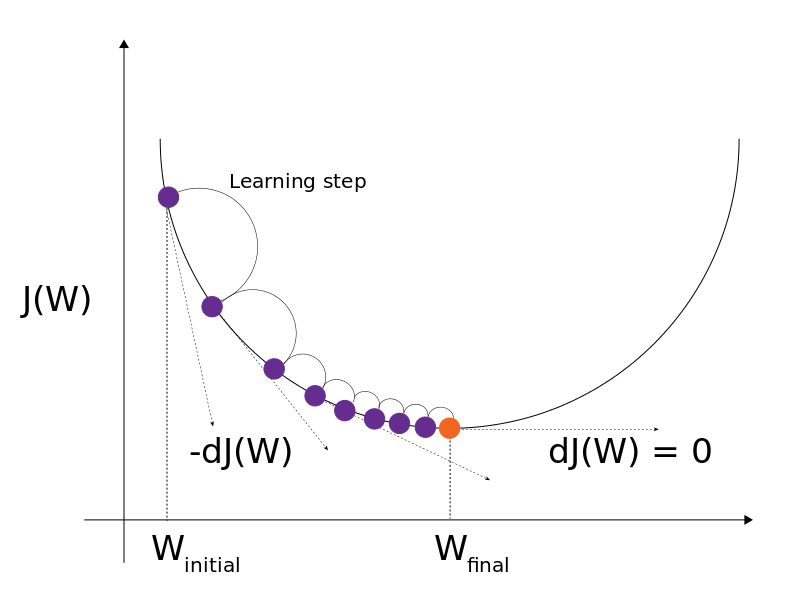

The objective of gradient descent is to minimize the cost by updating the parameters in the model. Because we have two parameters **W** and **b**, we have two update equations:


$$\begin{array}{l}
\mathrm{W}=\mathrm{W}-\left(\mathrm{learning}\;\mathrm{rate}\cdot \mathrm{dW}\right)\\
\mathrm{b}\;\;=\mathrm{b}\;\;-\left(\mathrm{learning}\;\mathrm{rate}\cdot \mathrm{db}\right)
\end{array}$$
 

where the learning rate hyperparameter is a positive constant value that controls how fast we move along the gradient. Further, `dW` and `db` are the gradients we computed from back propagation. We can perform gradient descent for `w` and `b` using the code below:

learning_rate = 0.05;
w = w - (learning_rate .* dW)

w =    -0.1769
   -1.4418
   -0.0727
   -1.3686
   -1.4621
   -0.0246
    1.2845
   -2.7907
   -1.3110


b = b - (learning_rate .* db)

b =     1.4754
    0.4140
    0.4951
    2.1199
   -0.4965
    0.4568
   -0.3635
    0.9546
    0.4000
   -0.5168


## Optimizing the logistic regression model using forward and backward propagation

Now that we did a single pass of forward and backward propagation with our logistic regression model, let's make an algorithm that uses all the components we described so far to optimize the two parameters `w` and `b` after 500 iterations. Note that in machine learning jargon, an iteration of both forward and backward prop is called an **epoch. **First, let's re-initialize the variables we used in forward propagation, cost computation, and backward propagation:

% Re-intialize variables
epoch = 1000; learning_rate = 0.05; numberOfOutputNodes = 1; % Hyperparameters
m = size(Xtrain, 1);                               % Constant scalar
actFnc = 'Sigmoid';                                % Sigmoid activation function
w = randn([size(Xtrain, 2), numberOfOutputNodes]); % Number of Xtrain features x number of responses
b = randn([size(Xtrain, 1), 1]);                   % Number of observations

Next, we need to write an expression that will allow us to loop all three steps several times, while simultaneously updating the weights and biases after each iterations. 

for i = 1:epoch % Iterate 500 times
    % 1. Forward propagation
    Z = Xtrain * w + b; 
    ypred = activationFnc(Z, actFnc);
    
    % 2. Cost evaluation -> store the costs for plot
    J(i) = costFunction(Ytrain, ypred, 'Log-Loss');
    
    % 3. Back propagation
    dZ = ypred - Ytrain; 
    dW = (1/m) .* (Xtrain' * dZ); 
    db = (1/m) .* sum(dZ, 2);
    
    % Gradient descent for iterative update
    w = w - (learning_rate .* dW);
    b = b - (learning_rate .* db);
end

### Visualizing the model error from the cost curve

This is how we obtain the final trained model from forward and backward propagation. Note that we saved the cost for both class predictions during our `for` loop. Let's now plot the cost curve using the cost values `J` against the number of epochs to see how much the error decreased over each training period:

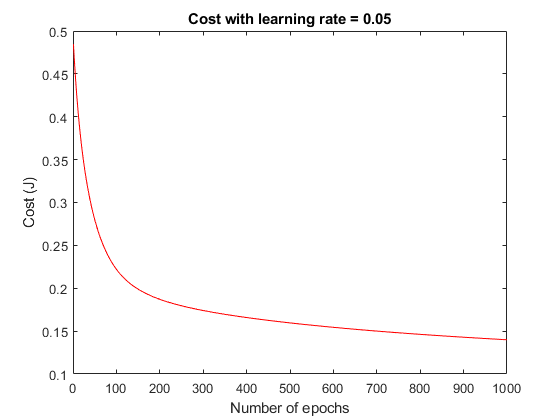

% Cost curve
figure; plot(1:epoch, J, 'color', 'r');
title('Cost with learning rate = 0.05'); 
xlabel('Number of epochs'); ylabel('Cost (J)');

The cost value of using this logistic regression model with forward and backward propagation begins to approach a minimum value around 500 epochs, and has the shape of the **negative binomial distribution**, which is expected from logistic regression. 

How do the probability values we predict look?

ypred'

ypred =     0.9900
    0.9834
    0.9773
    0.0017
    0.9934
    0.9865
    0.0027
    0.9639
    0.9509
    0.0005


### Label encoding for classification

Several values are very close to 0 or 1, indicating that we made a good classifier. Let's transform these probabilities to labels {1, 0} for each respective class, using a p = 0.5 as the decision boundary and compute the training accuracy for both classes:

% Label encoding for classification
ypred(ypred > 0.5) = 1; % If the probability is greater than 50%, set it to malignant class 
ypred(ypred < 0.5) = 0; % Otherwise, set it to benign class

### Compute the logistic regression training accuracy

We can compute the binary clasification hold-out accuracy using the **zero-one loss** formulation:


$$\begin{array}{l}
\mathrm{Accuracy}=1-L\left(y,y_{\mathrm{pred}} \right)\\
\mathrm{Accuracy}=1-\mathrm{mean}\left(\mathrm{abs}\left(y_{\mathrm{pred}} -y\right)\right)
\end{array}$$


% Compute training accuracy using mean absolute deviation
train_accuracy = 1 - (sum(abs(ypred - Ytrain)) / m)

train_accuracy = 0.9678

### Logistic regression hold out accuracy

Let's now evaluate the hold-out accuracy of the model using the test dataset. 

% Used trained weights to compute ypred
clear ypred; Z = Xtest * w;
ypred = activationFnc(Z, actFnc);

% Label encode
ypred(ypred > 0.5) = 1; % If the probability is greater than 50%, set it to malignant class 
ypred(ypred < 0.5) = 0; % Otherwise, set it to benign class

To visualize the model's performance, let's plot the confusion matrix:

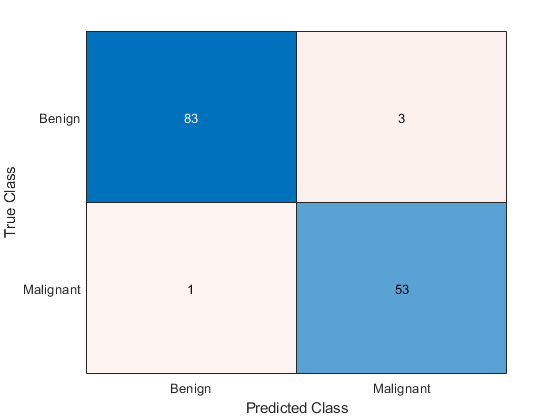

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: {'Benign'  'Malignant'}

  Show all properties


% Create confusion matrix
cm = confusionmat(Ytest, ypred);
figure; labels = {'Malignant', 'Benign'};
title('Logistic regression hold out accuracy');
confusionchart(cm, labels)

And let's compute other model statistics that we may be interested in:

TP  = cm(1, 1); FP = cm(1, 2); FN = cm(2, 1); TN  = cm(2, 2);
malignant_precision = (TP) / (TP + FP)

malignant_precision = 0.9815

malignant_recall    = (TP) / (TP + FN)

malignant_recall = 0.9464

benign_precision    = (TN) / (TN + FP)

benign_precision = 0.9881

benign_recall       = (TN) / (TN + FN)

benign_recall = 0.9651

average_cccuracy    = sum(diag(cm)) / sum(cm, 'all')

average_cccuracy = 0.9714

malignant_accuracy  = TP / sum(cm(1, :), 2)

malignant_accuracy = 0.9815

benign_accuracy     = TN / sum(cm(2, :), 2)

benign_accuracy = 0.9651

MCC                 = (TP * TN - FP * FN) / ...
                    sqrt(((TP + FP)*(TP + FN)*(TN + FP)*(TN + FN)))

MCC = 0.9405

### Evaluating logistic regression cross validation accuracy

Now what if we wanted to truly validate our logistic regression classifier with forward/backward propagation? We can use the following cross validation schematic shown below:

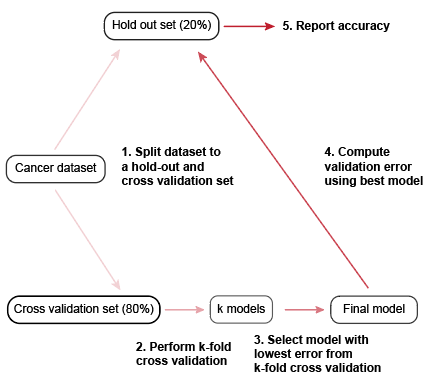

To save space, the procedure described previously has been refectored into the `crossValidate` function. The documentation for the function is shown below:

kfold = 10; type = 'Logistic'; trainingSize = 0.8; randomState = 2;

% Run cross validation
Summary = crossValidate(trainingSize, randomState, ...
                            hyperparameters, kfold, type)

Summary = struct with fields:
                     cm: [2×2 double]
           NormalizedCM: [2×2 double]
    malignant_precision: 0.9524
       benign_precision: 0.9722
       malignant_recall: 1
          benign_recall: 1
       average_cccuracy: 0.9821
                    MCC: 0.9623
     malignant_accuracy: 0.9524
        benign_accuracy: 1


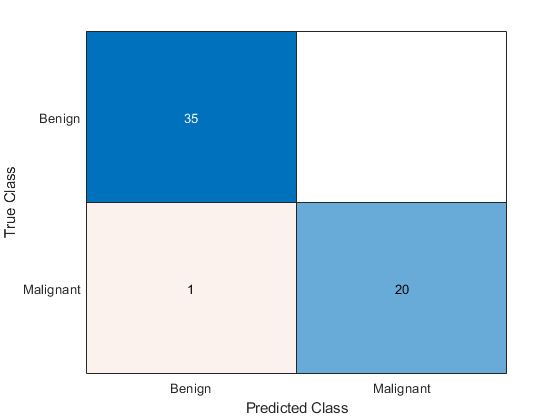

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: {'Benign'  'Malignant'}

  Show all properties


% Plot confusion matrix
figure; title('Confusion matrix from 10-fold cross validation');
labels = {'Malignant', 'Benign'};
confusionchart(Summary.cm, labels)

## Applying forward and backward propagation to the shallow neural network

Now that we constructed a logistic regression model that performs forward and backward propagation, let's return back to the original model we wanted to build - the neural network with 1 hidden layer. We'll set the number of nodes in the hidden layer equal to 2. The schematic for the model we're training and a summary of the computations performed is shown below:

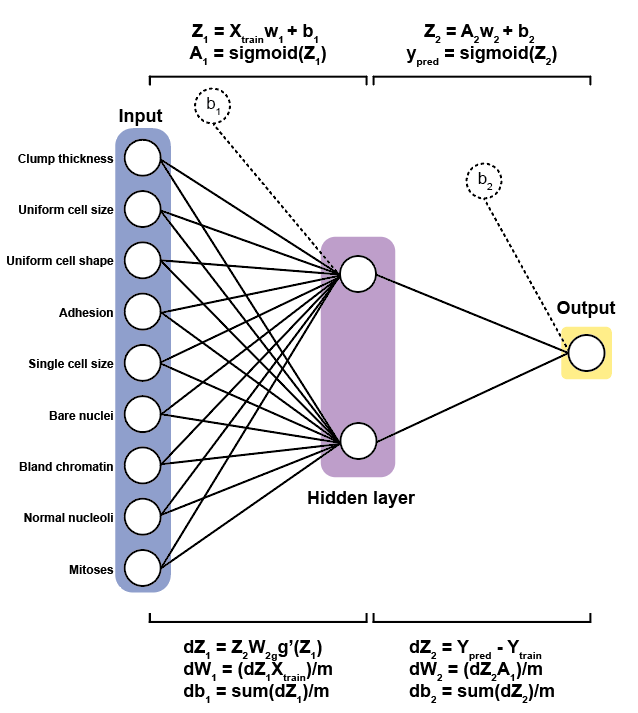

### Forward propagation

First let's initialize some parameters and hyperparameters. This time, we'll have 4 parameters to compute: weights and biases between input and hidden layer `(w1, b1)`, and weights / biases between hidden and output layer `(w2, b2)`. 

% Intialize the hyperparameters 
numberOfHiddenNodes = 2; actFnc = 'Sigmoid';

% Intialize the weights and biases. 
w1 = randn([size(Xtrain, 2), numberOfHiddenNodes]) % Size of w1 should be number of features x number of hidden nodes

w1 =    -0.7165   -0.2843
    0.1266    2.2534
   -0.7474    0.2796
   -0.2567   -3.1864
   -0.6700    0.7519
   -0.1549    0.1054
    1.4176    0.3045
   -1.4444    2.0343
    0.4014    0.5089


b1 = randn(size(Xtrain, 1), 1)                     % Size should be number of obs x 1

b1 =    -0.1852
    0.9929
    0.3538
    0.6472
   -0.0293
    0.8677
   -2.0031
   -0.2556
   -1.9564
    0.6787


Let's now 1 forward step from the input layer -> hidden layer.

Z1 = Xtrain * w1 + b1

Z1 =     1.4164   -1.7684
    3.1940   -0.4616
    1.1924   -1.5322
   -1.6776    1.1756
    0.3798   -0.2385
    1.6466    0.9846
   -4.7886    2.8462
    1.4369   -1.9119
   -0.5183   -3.7137
   -4.9737   12.1089


A1 = activationFnc(Z1, actFnc)

A1 =     0.8048    0.1457
    0.9606    0.3866
    0.7672    0.1777
    0.1574    0.7642
    0.5938    0.4407
    0.8384    0.7280
    0.0083    0.9451
    0.8080    0.1288
    0.3733    0.0238
    0.0069    1.0000


Now that we have the transformed values stored in `A1`, we'll use this data and transform it 1 more time using forward propagation. First, let's initialize the weights and biases:

w2 = randn([size(A1, 2), size(Ytrain(:, 1), 2)]) % Size of w2 needs to be number of features in A1 x number of classes

w2 =     0.2446
    0.3691


b2 = randn(size(A1, 1), 1)                       % Size of b2 needs to be number of obs x 1

b2 =     2.0336
    0.1938
    0.3045
    0.3755
   -0.4961
    0.2166
    0.1855
   -0.0052
   -2.0342
    0.0480


Finally, let's move 1 forward step from the hidden layer -> output layer. We'll use the same activation function we used in the previous step.

Z2 = A1 * w2 + b2

Z2 =     2.2842
    0.5715
    0.5577
    0.6961
   -0.1882
    0.6903
    0.5364
    0.2400
   -1.9341
    0.4187


Because this is the last step, the final transformed dataset is our predicted value `ypred`

ypred = activationFnc(Z2, actFnc)

ypred =     0.9076
    0.6391
    0.6359
    0.6673
    0.4531
    0.6660
    0.6310
    0.5597
    0.1263
    0.6032


 That's forward propagation with 1 hidden layer. Next, we need to evaluate the cost.

### Cost evaluation

To evaluate the cost, let's use the cross entropy loss function:

LossFunction = 'Log-Loss';
J = costFunction(Ytrain, ypred, LossFunction)

J = 0.7652

### Backward propagation

We went over the derivative terms for a single step of back propagation, and the computation from the outer layer to the hidden layer will be the same:

**Output layer to hidden layer: **

- 
$$\textrm{dZ2}=Y_{\textrm{pred}} -Y_{\textrm{train}} \;$$


- 
$$d\textrm{W2}=\textrm{dZ2}\cdot {\textrm{A1}}^T \cdot \frac{1}{m}$$


- 
$$\;\textrm{db2}=\;\textrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ2}\right)$$


First let's compute the error from the output $\textrm{dZ2}=Y_{\textrm{pred}} -Y_{\textrm{train}}$

dZ2 = ypred - Ytrain

dZ2 =    -0.0924
   -0.3609
   -0.3641
    0.6673
   -0.5469
   -0.3340
    0.6310
   -0.4403
   -0.8737
    0.6032


Next, we have to compute how much error our weights contributed to the overall error in proportion to `dZ.` $\frac{1}{m}$ normalizes our error term by the number of observations in the dataset: $d\textrm{W2}=\frac{1}{m}\left(\textrm{dZ}\cdot {\textrm{A1}}^T \right)$

m = size(Xtrain, 1) % m = number of observations in training set

m = 559

dW2 = (1/m) .* (A1' * dZ2)

dW2 =    -0.1612
    0.0666


Finally, we compute the error in the bias term, which is the sum of the errors from the output layer normalized based on the number of observations in the data: 


$$\;\textrm{db2}=$$
 
$$\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ2}\right)$$
 

db2  = (1/m) .* sum(dZ2, 2)

db2 =    -0.0002
   -0.0006
   -0.0007
    0.0012
   -0.0010
   -0.0006
    0.0011
   -0.0008
   -0.0016
    0.0011


**Hidden layer to input layer: **

The computation for the hidden layer to the input layer will essentially be the same, except for computing `dZ1.` This time, we need to compute the error generated from the activation function, `g'(Z1)`:

- 
$$\textrm{dZ1}={\textrm{W2}}^T \cdot \textrm{Z2}\cdot g^{\prime } \left(\textrm{Z1}\right)$$


- 
$$d\textrm{W1}=\frac{1}{m}\left(\textrm{dZ1}\cdot {X_{\textrm{train}} }^T \right)$$


- 
$$\;\textrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ1}\right)$$


As noted earlier, the activation function does have its own error term $g^{\prime } \left(\textrm{Z1}\right)$. For the sigmoid activation function derivative term: $g^{\prime } \left(\textrm{Z1}\right)\;=\left(1-{\textrm{A2}}^2 \right)$. 

However, the ReLU and leaky ReLU are nice in that there is no derivative! Instead, we can use the following rule sets:


$${g^{\prime } \left(Z\right)}_{\textrm{ReLU}} =\left\lbrace \begin{array}{cc}
1 & \textrm{if}\;Z>0\\
0 & \textrm{if}\;Z\le 0
\end{array}\right.$$



$${g^{\prime } \left(Z\right)}_{\textrm{Leaky}\;\textrm{ReLU}} =\left\lbrace \begin{array}{cc}
1 & \textrm{if}\;Z>0\\
\varepsilon  & \textrm{if}\;Z\le 0
\end{array}\right.$$


Let's repeat the final step of back propagation, using the sigmoid activation function gradient: $\textrm{dZ1}={\textrm{W2}}^T \cdot \textrm{Z2}\cdot g^{\prime } \left(\textrm{Z1}\right)$

dZ1  = (w2 * dZ2') .* (1 - A1.^2)'

dZ1 =    -0.0080   -0.0068   -0.0366    0.1592   -0.0866   -0.0243    0.1543   -0.0374   -0.1839    0.1475   -0.0116   -0.0270   -0.0585   -0.0159   -0.0944    0.1229    0.1384   -0.0399    0.1362   -0.0564   -0.0617   -0.0288   -0.0671   -0.0254    0.0559    0.0125   -0.0440   -0.0173   -0.0229    0.1507   -0.0708    0.2089   -0.0301   -0.0820    0.1810   -0.0086   -0.1131   -0.1036    0.0278   -0.0202   -0.0079   -0.1750   -0.0138   -0.0209   -0.0040   -0.0102    0.1994    0.1997    0.1187    0.0795
   -0.0334   -0.1133   -0.1301    0.1025   -0.1627   -0.0579    0.0249   -0.1598   -0.3223    0.0000   -0.0507   -0.0017   -0.0944   -0.1619   -0.2811    0.0018    0.0002   -0.2280    0.0027   -0.1586   -0.2890   -0.1080   -0.1167   -0.2452    0.0857    0.1297   -0.1321   -0.0527   -0.1242    0.0444   -0.2492    0.0002   -0.1009   -0.2021    0.0107   -0.0824   -0.2022   -0.2472    0.0018   -0.2057   -0.0620   -0.2809   -0.0803   -0.0975   -0.0501   -0.0368    0.3010    0.0001    0.0000   

Next, let's compute dW1: $\frac{1}{m}\left(\textrm{dZ1}\cdot {X_{\textrm{train}} }^T \right)$

dW1  = (1/m) .* Xtrain' * dZ1'

dW1 =     0.0541    0.0711
    0.0649    0.0746
    0.0661    0.0750
    0.0535    0.0792
    0.0508    0.0594
    0.0650    0.0858
    0.0619    0.0735
    0.0606    0.0593
    0.0338    0.0331


Finally, we need to compute the cost for the biases: $\;\textrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ1}\right)$

db1  = (1/m) .* sum(dZ1', 2)

db1 = 	1.0e+-3 *

   -0.0740
   -0.2149
   -0.2983
    0.4681
   -0.4459
   -0.1470
    0.3205
   -0.3528
   -0.9055
    0.2639


### Gradient descent

Now that we computed the gradients, let's compute the updated weights and biases using gradient descent:

learning_rate = 0.05;
w2 = w2 - (learning_rate .* dW2)

w2 =     0.2527
    0.3657


b2 = b2 - (learning_rate .* db2)

b2 =     2.0336
    0.1938
    0.3045
    0.3755
   -0.4961
    0.2166
    0.1855
   -0.0052
   -2.0341
    0.0479


w1 = w1 - (learning_rate .* dW1)

w1 =    -0.7192   -0.2879
    0.1234    2.2496
   -0.7507    0.2759
   -0.2594   -3.1904
   -0.6726    0.7489
   -0.1581    0.1011
    1.4145    0.3008
   -1.4475    2.0314
    0.3997    0.5073


b1 = b1 - (learning_rate .* db1)

b1 =    -0.1851
    0.9929
    0.3539
    0.6471
   -0.0293
    0.8677
   -2.0031
   -0.2556
   -1.9564
    0.6787


## Optimizing the neural network for the ovarian cancer data set

Now that we have all the steps required to train, evaluate, and optimize a shallow neural network, we would iterate this until the cost value reaches a minimum. 

To save space for iteratively running the shallow neural network we just wrote, we created an accessory function `SNN.` It it modularized to the three steps we performed: forward propagation, evaluating the cost, and back propagation. The docstring is provided below:

### Training and optimizing the shallow neural network

Let's now use this function to train a neural network using the ovarian cancer dataset:

% Specify hyperparameters to train the model and store in structure
hyperparameters.numOfActiveNodes = 2; hyperparameters.alpha = 0.05;
hyperparameters.epoch            = 500; hyperparameters.actFnc = 'Sigmoid';
hyperparameters.randomstate      = 2;

% Train the shallow neural network model
model = SNN(Xtrain, Ytrain, hyperparameters)

model = struct with fields:
     ypred: [559×1 double]
         J: [500×1 double]
        w2: [2×1 double]
        b2: [559×1 double]
        w1: [9×2 double]
        b1: [559×1 double]
    actFnc: 'Sigmoid'


### Evaluating the costs

Now that we have a trained model, let's evaluate the results. First, let's plot the cost with respect to the number of iterations we made in the model:

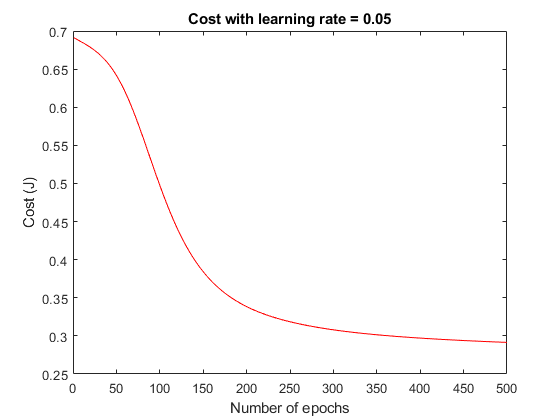

figure; epoch = 500;
plot(1:epoch, model.J, 'color', 'r');
title('Cost with learning rate = 0.05');
xlabel('Number of epochs'); ylabel('Cost (J)');

Before we evaluate the model, we should discuss how to optimize the model's hyperparameters.

## Hyperparameter tuning

Hyperparameter tuning is finding the best set of hyperparameters that will optimize the k-fold cross validation accuracy of our model without overfitting. There are two strategies we can use: a complete grid search, and a random grid search.

### Complete Grid Search

So far, we have discussed the following set of hyperparameters:

- Number of activation nodes for each layer (Number of potential parameters: L layers * n nodes).

- The learning rate (Number of potential parameters: 100, assuming we sample [0.01, 1] in 0.01 increments. Estimate is higher if we want to explore lower / higher values).

- The number of epochs / iterations (Number of potential parameters: 500).

- The activation function (Number of potential parameters: 3).

n = 100 * 100 * 500 * 3;
disp("Number of posible parameter combinations to sample: " + string(n))

There are about $15,000,000$ different possible combinations from 4 parameters to sample, not including the training/test size and optimizing the number of k-folds in cross validation. 

A **complete grid search** explores every single combination. While the code is shown for running an exhaustive grid search, another (preferred) method that balances the amount of time searching for an optimal model and model performance is a random grid search, discussed below.

To run a comprehensive grid search, we can use the following code which uses a custom script called `CompleteGridSearchCV`. We will not run this code in practice.

### Random Grid Search

A **random grid search** takes in a random combination of hyperparameters to find the best set of hyperparameters to use. There are several benefits to randomized grid search, namely that the search time is decreased by A LOT. Instead of searching every single combination of parameters, we can chose the number of times we want to run our random search (ie 30 times) to get the best hyperparameters. Additionally, [Bergestra and Bengio, 2012](http://www.jmlr.org/papers/volume13/bergstra12a/bergstra12a.pdf) found that random search can perform just as well, if not better, than a grid search. 

To run a random grid search, we can use the following code, which uses the script `RandomGridSearchCV` located in the lesson folder. 

% Get distribution of parameters
sampleActivationNodes = [2:100];      % Number of activation nodes to sample
sampleAlpha = linspace(0.01, 1, 100); % Number of alpha values to sample
sampleEpochs = [1:1000];              % Number of epochs to sample
sampleActFnc = [1, 2, 3];             % Activation functions to sample

% Parameters that we're keeping constant
trainingSize = 0.8; kfold = 10;
type = "SNN"; iterations = 30;

% Run Random Grid Search with k-fold cross validation

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30



Index exceeds the number of array elements (0).

Error in RandomGridSearchCV (line 25)
    bestParameters = cache{idx};

bestParameters = RandomGridSearchCV(iterations, ...
    sampleActivationNodes, sampleAlpha, sampleEpochs, sampleActFnc, ...
    trainingSize, kfold, type);   

One set of optimal solutions obtained from random grid search found that 82 hidden nodes, a learning rate of 0.91, 64 epochs, and the leaky ReLU resulted in the best model after 30 iterations. We'll use these hyperparameters to benchmark the neural network.

### Benchmarking the shallow neural network using 10-fold cross validation

We'll benchmark our shallow neural network using the hyperparameters from the random grid search. We'll perform 10-fold cross validation, and compare our results against the logistic regression classifier.

% Set the hyperparameters to use from random grid search
hyperparameters.numOfActiveNodes = 82;
hyperparameters.alpha = 0.91;
hyperparameters.epoch = 64;
hyperparameters.actFnc = 'Leaky ReLU';
hyperparameters.randomstate = 2;

% Perform 10-fold cross validation
kfold = 10; type = 'SNN';
trainingSize = 0.8; randomState = 2;
nnCM = crossValidate(trainingSize, randomState, ...
                            hyperparameters, kfold, type)

nnCM = struct with fields:
                     cm: [2×2 double]
           NormalizedCM: [2×2 double]
    malignant_precision: 1
       benign_precision: NaN
       malignant_recall: 0.3750
          benign_recall: 0
       average_cccuracy: 0.3750
                    MCC: NaN
     malignant_accuracy: 1
        benign_accuracy: 0


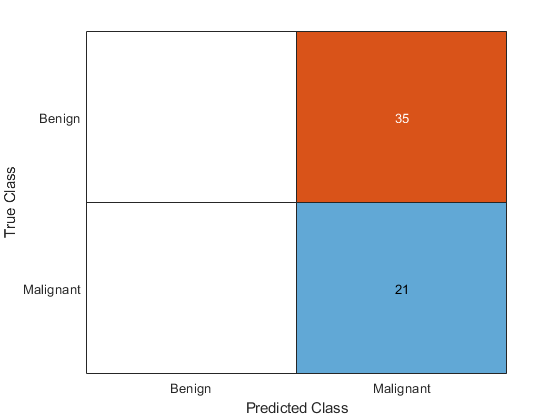

% Plot confusion matrix
figure; title('Confusion matrix from 10-fold cross validation');
labels = {'Malignant', 'Benign'};
confusionchart(nnCM.cm, labels);

### Assessing model accuracy

#### Hold out

Next, let's use the test set to evaluate how our shallow neural network model does with the validation set.

% Used trained weights to compute ypred
clear ypred; 
Z1 = Xtest * model.w1; A1 = activationFnc(Z1, actFnc);
Z2 = A1    * model.w2; ypred = activationFnc(Z2, actFnc);

% Label encode
ypred(ypred > mean(ypred)) = 1; % If the probability is greater than 50%, set it to malignant class 
ypred(ypred < mean(ypred)) = 0; % Otherwise, set it to benign class

To visualize the model's performance, let's plot the confusion matrix:

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: {'Benign'  'Malignant'}

  Show all properties


% Create confusion matrix
cm = confusionmat(Ytest, ypred);
figure; labels = {'Malignant', 'Benign'};
title('Shallow neural network hold out accuracy');
confusionchart(cm, labels)

And let's compute other model statistics that we may be interested in:

TP  = cm(1, 1); FP = cm(1, 2); FN = cm(2, 1); TN  = cm(2, 2);
malignant_precision = (TP) / (TP + FP)

malignant_precision = 0.9815

malignant_recall    = (TP) / (TP + FN)

malignant_recall = 0.9464

benign_precision    = (TN) / (TN + FP)

benign_precision = 0.9881

benign_recall       = (TN) / (TN + FN)

benign_recall = 0.9651

average_cccuracy    = sum(diag(cm)) / sum(cm, 'all')

average_cccuracy = 0.9714

malignant_accuracy  = TP / sum(cm(1, :), 2)

malignant_accuracy = 0.9815

benign_accuracy     = TN / sum(cm(2, :), 2)

benign_accuracy = 0.9651

MCC = 0.9405

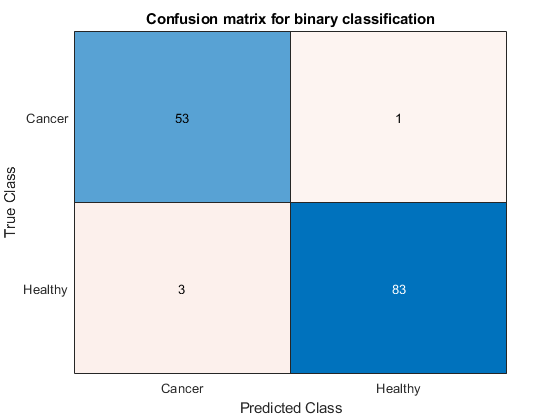

Summary = struct with fields:
           cm: [2×2 double]
    Precision: 0.9815
       Recall: 0.9464
     Accuracy: 0.9714
       Class1: 0.9815
       Class2: 0.9651
      F1score: 0.9636
          MCC: 0.9405


Hold-out malignant classification accuracy:0.98148


Hold-out benign classification accuracy:0.96512


Hold-out average classification accuracy:0.97143


MCC                 = (TP * TN - FP * FN) / ...
                    sqrt(((TP + FP)*(TP + FN)*(TN + FP)*(TN + FN)))

#### k-fold cross validation

Let's now run **k-fold cross validation** and obtain a relatively unbiased estimate of the test error. 

kfold = 10; type = 'SNN'; trainingSize = 0.8; randomState = 2;

% Run cross validation
Summary = crossValidate(trainingSize, randomState, ...
                            hyperparameters, kfold, type)

Summary = struct with fields:
                     cm: [2×2 double]
           NormalizedCM: [2×2 double]
    malignant_precision: 0.9048
       benign_precision: 0.9444
       malignant_recall: 0.9500
          benign_recall: 0.9714
       average_cccuracy: 0.9464
                    MCC: 0.8853
     malignant_accuracy: 0.9048
        benign_accuracy: 0.9714


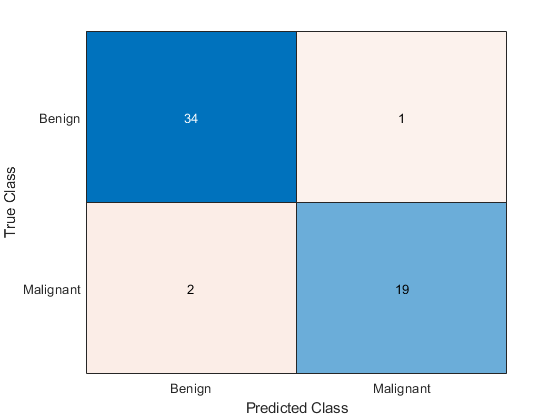

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: {'Benign'  'Malignant'}

  Show all properties


% Plot confusion matrix
figure; title('Confusion matrix from 10-fold cross validation');
labels = {'Malignant', 'Benign'};
confusionchart(Summary.cm, labels)

## Issues in training neural networks

While neural networks are really popular for artificial intelligence research and applications, [there are issues with training them](https://machinelearningmastery.com/why-training-a-neural-network-is-hard/). 

### Initializing values for w and b

Earlier, we initialized our values for w and b to be small random numbers. Is this the best choice for w and b? We discuss 2 alternative cases that are different from our random intiialization of small numbers: if w and b are all zeros and all ones.

#### Setting w and b to be all zeros

We'll go back to our synthetic dataset with 50 observations and 6 features and plot the results when w and b are all zero.

rng(2);

Xtrain = normrnd(0, 1, [50, 6]);

w = [0, 0, 0, 0, 0, 0];
b = zeros([50, 1]);
Z = Xtrain * w' + b;

figure;
plot(Z); hold on; plot(activationFnc(Z, 'Sigmoid')); hold off;
legend({'Z', 'Sigmoid(Z)'});
ylim([-0.1 0.6]);
xlabel('Observations'); ylabel('Z or sigmoid(Z)');

If the values are all zeros, the neural network stops learning the features - they will be stuck at Z = 0 and A = 0.5 during every iteration.

#### Setting w and b to be all ones

Let's see what happens when we set w and b to be all ones:

w = [1, 1, 1, 1, 1, 1];
b = ones([50, 1]);
Z = Xtrain * w' + b;

figure;
plot(Z); hold on; plot(activationFnc(Z, 'Sigmoid')); hold off;
legend({'Z', 'Sigmoid(Z)'});
xlabel('Observations'); ylabel('Z or sigmoid(Z)');

As you can see, our features (blue) end up being transformed to log-odds in the range [0, 1] (red) by the activation function. Thus, the neural network algorithm essentially becomes a logistic regression classifier when using the sigmoid activation function and the biases are all equal to 1.

#### Symmetry breaking

**Symmetry breaking** is a phenomenon where very small, random fluctuations in a system are able to influence the outcome. By randomly initializing w and b to be small random numbers, we don't break the algorithm from the beginning and we allow the neural network to approach a better solution through back propagation / gradient descent.

### Overfitting

Recall that the underlying objective in machine learning is to build a model that balances the model's ability to minimize bias and variance (the **bias-variance tradeoff**). Neural networks are complex models and are susceptible to overfitting noise in a dataset. 

To address this potential issue, one potential solution is to use **regularization (ie Ridge or LASSO)** in the loss function and gradients. Recall that the regularized term is a function of the coefficients (the most important ones being weights) and a tuning factor $\lambda$. Regularization reduces overfitting by penalizing the weights. 

The following code imposes ridge regularization on the cross entropy loss function and subsequent back propagation for our shallow neural network:

Note that `lambda` is the ridge regularization term, and would be another hyperparameter we have to tune if we decide to regularize our neural network. 

### Data scaling

While neural networks can capture trends in complex / non-standardized datasets, there are several advantages to train using standardized data:

- We reduce the training time because we're examining a smaller range of values and thus reducing the time it takes for the weights to converge to an optimal value.

- We reduce the change of getting stuck in a local optima when computing the loss due to chance by minimizing the dynamic range of the data.

Recall that there are two common ways to scale our data depending on how we wish to interpret each feature: the **Z-score method**, and the **min-max scaling method**. The z-score method will ensure that each value is scaled to have a mean of 0 and standard deviation of 1. 


$$X_{z-\textrm{score}} =\frac{X_{\textrm{ij}} -\textrm{mean}\left(X_j \right)}{\textrm{std}\left(X_j \right)}$$


While useful, scaling in this manner can produce results that don't necessarily reflect true values, especially if our feature is composed of only positive values. In those cases, min-max scaling can actually be better, where we scale the data point from a value of 0 to 1 for values that are only positive:


$$X_{\min -\max } =\frac{X_{\textrm{ij}} -\min \left(X_j \right)}{\max \left(X_j \right)-\min \left(X_j \right)}$$


### Determining the best neural network structure to use.

Recall that we've been using a naive approach to determining the number of activation nodes in our neural network, where we assumed two activation nodes are best because we're trying to split the data into two classes. While it's a good starting point, it's another assumption we're imposing on the model.

To determine the best number of activation nodes to use for either a single layer or `L` layers, we need to optimize this hyperparameter in a systematic way. One way to do so is to run k-fold cross validation, and see which number of activation nodes best improves the accuracy / minimzes the error from the model. 

### Shallow neural network

Let's re-train our neural network and compare the two results

clearvars -except logisticCM Xtrain Ytrain Xtest Ytest;
rng(2);

% Set the hyperparameters to use
hyperparameters.numOfActiveNodes = 82;
hyperparameters.alpha = 0.91;
hyperparameters.epoch = 64;
hyperparameters.actFnc = 'Leaky ReLU';
hyperparameters.randomstate = 2;

% Perform 10-fold cross validation
kfold = 10;
type = 'SNN';
trainingSize = 0.8;
randomState = 2;

nnCM = crossValidate(trainingSize, randomState, ...
                            hyperparameters, kfold, type)
% Plot confusion matrix
figure; title('Confusion matrix from 10-fold cross validation');
labels = {'Malignant', 'Benign'};
confusionchart(nnCM.cm, labels);

### Results

The shallow neural network slightly outperforms the logistic regression classifier with the given set of hyperparameters. 

At this point, or even earlier in the lecture, you may have been wondering how we selected the hyperparameters to use in the examples above. Currently, we have not explored a systematic way to determine which hyperparameters to use. We will discuss two strategies in the section below.

## Summary

In this lecture, we trained a shallow neural network on breast cancer imaging data and evaluated its performance. Additionally, we discussed how training a neural network can be challenging, and some common pitfalls. Finally, we benchmarked the neural network against a logistic regression classifier, and found that the neural network outperformed the logistic regression classifier.

## Useful reading and references

- A [generalized tutorial for learning about neural networks](https://medium.com/datathings/neural-networks-and-backpropagation-explained-in-a-simple-way-f540a3611f5e) that is language-agnostic.

- The [various flavors of neural networks](https://towardsdatascience.com/the-mostly-complete-chart-of-neural-networks-explained-3fb6f2367464), and how they are currently being used in real-world settings.

- Heuristics on deciding [how many hidden layers and activation nodes](https://machinelearningmastery.com/how-to-configure-the-number-of-layers-and-nodes-in-a-neural-network/) to initialize in a neural network.

- [Other activation functions, their usage, and generalizations about pros/cons](https://medium.com/@himanshuxd/activation-functions-sigmoid-relu-leaky-relu-and-softmax-basics-for-neural-networks-and-deep-8d9c70eed91e).

- [Andrew Ng's CS229 deep learning notes ](http://cs229.stanford.edu/notes/cs229-notes-deep_learning.pdf)for a more in-depth understanding of the mathematics and algorithms for constructing neural networks from scratch.

- The [deep learning specialization on Coursera](https://www.coursera.org/specializations/deep-learning) (also taught by Andrew Ng and others at [deeplearning.ai](https://www.deeplearning.ai/)). It consists of 5 courses, all on deep learning and optimizing these models. The course is taught in Python with the specific usage of the `numpy` and `scipy` libraries.

- [Deep Learning](http://www.deeplearningbook.org/) by Ian Goodfellow and Yoshua Bengio - two pioneers in modern deep learning. The book covers 1-2 semester's worth of material for not the basics of constructing and applying deep neural networks, but more cutting-edge techniques in Artificial Intelligence